# Viewing Mismatched Filters With Various Lengths

clear; close all 

## Chip Sequence

chipSeqBarker = [1 1 1 1 1 -1 -1 1 1 -1 1 -1 1]'; % Barker 13
chipSeqBarker =repmat(chipSeqBarker,1,3).';
chipSeqBarker = chipSeqBarker(:);

nsamp = 20;
chipSeqRand = exp(1i*2*pi*rand(nsamp,1));
chipSeqRand =repmat(chipSeqRand,1,2).';
chipSeqRand = chipSeqRand(:);

chipSeq = chipSeqRand; % CHANGE BETWEEN chipSeqRand and chipSeqBarker
K = numel(chipSeq); % K chips

## Matched Filter

[mf,psl,isl,lag] = getNormalizedAC(chipSeq,chipSeq);
fprintf('Matched Filter: PSL: %f  ISL: %f\n',psl,isl)

Matched Filter: PSL: -10.121963  ISL: -0.312429


## Create Inputs for Least Squares (LS)

M = 4*K; % M taps in FIR filter. Should be >= K
d = getIdealVec(M,K);
C = getBandedMat(K,M,chipSeq);

## LS Solution fo MMF

Perform LS computation

% z = inv(C'*C)*C'*d; % Easy to read computation
z = (C'*C)\(C'*d);    % Recommended workflow in MATLAB

[mmf,psl,isl] = getNormalizedAC(z,chipSeq);
fprintf('Mismatched Filter: PSL: %f  ISL: %f\n',psl,isl)

Mismatched Filter: PSL: -23.103004  ISL: -13.034865


xvals = -ceil(numel(mmf)/2-1):floor(numel(mmf)/2);

## Animation Plot

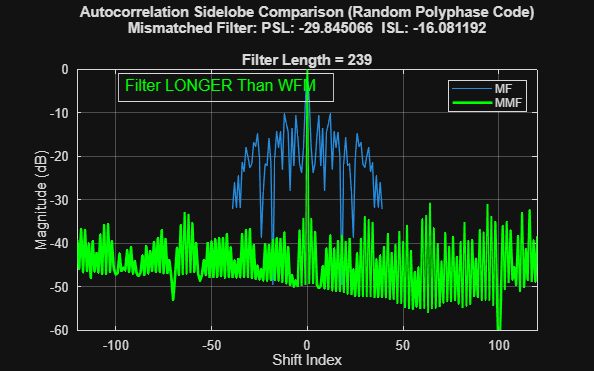

f1 = figure;
f1.Position(3:4) = [800,500];
ax = gca;
mfPlot = plot(ax,lag,mf,'DisplayName','MF');
hold(ax,'on')
mmfPlot = plot(NaN,NaN);
xlabel(ax,'Shift Index')
ylabel(ax,'Magnitude (dB)')
legend
ylim(ax,[-70 0])
xlim([-120,120])
grid on

dim = [.2 .5 .3 .3];
str = 'Filter SHORTER Than WFM';
txtbox = annotation('textbox',dim,'String',str,'FitBoxToText','on');
txtbox.FontSize = 12;
txtbox.Color = 'red';

for mm = 3:2:6*K
    d = getIdealVec(mm,K);
    C = getBandedMat(K,mm,chipSeq);
    z = (C'*C)\(C'*d);    % Recommended workflow in MATLAB
    [mmf,psl,isl] = getNormalizedAC(z,chipSeq);
    slString = sprintf('Mismatched Filter: PSL: %f  ISL: %f\n',psl,isl);
    nString = sprintf('Filter Length = %d',mm);
    if numel(chipSeqBarker) == numel(chipSeq) && all(chipSeqBarker == chipSeq)
        title(ax,{'Autocorrelation Sidelobe Comparison (Barker-13 Code)',slString,nString})
    else
        title(ax,{'Autocorrelation Sidelobe Comparison (Random Polyphase Code)',slString,nString})
        ylim(ax,[-60 0]);
    end
    xvals = -ceil(numel(mmf)/2-1):floor(numel(mmf)/2);
    delete(ax.Children(1))
    mmfPlot = plot(ax,xvals,mmf,'g','DisplayName','MMF','LineWidth',2);
    if mm > K
        txtbox.String = 'Filter LONGER Than WFM';
        txtbox.Color = 'green';
    end
    pause(.1)
end

## Helper Functions

function [ac,psl,isl,lag] = getNormalizedAC(z,chipSeq)
    if isequal(size(z), size(chipSeq)) && all(z == chipSeq)
        [ac,lag] = xcorr(chipSeq);
    else
        ac = conv(z,chipSeq);
    end
    ac = mag2db(abs(ac));
    ac = ac - max(ac);
    [psl,isl] = sidelobelevel(ac);
end

function [vec,p] = getIdealVec(M,K)
    % Create ideal response for LS computation
    % Index of peak in ideal response
    if mod(M+K,2) == 0 % M is even
        p = (M+K)/2;
    else
        p = (M+K-1)/2; % M is odd
    end
    
    % Ideal response vector
    % All zeros except "middle" element is 1
    vec = zeros(M+K,1);
    vec(p) = 1;
end

function C = getBandedMat(K,M,code)
    % Banded Matrix C
    C = zeros(K+M,M);
    for m = 1:M
        C((1:K)+m-1, m) = code(:);
    end
end